# Homework 4

## Exercise 24.1.3 (Stewart 14.5.1)

% Did this by hand, just checking work (this exercise only)
syms t z(t) x(t) y(t);

x(t) = sin(t)

$$x(t) = \sin\left(t\right)$$

y(t) = exp(t)

$$y(t) = {\mathrm{e}}^{t}$$

z(t) = x(t)^2 + y(t)^2 + (x(t) * y(t))

$$z(t) = {\sin\left(t\right)}^{2}+{\mathrm{e}}^{t}\,\sin\left(t\right)+{\mathrm{e}}^{2\,t}$$


dzdt = simplify(diff(z, t))

$$dzdt(t) = 2\,{\mathrm{e}}^{2\,t}+{\mathrm{e}}^{t}\,\cos\left(t\right)+2\,\cos\left(t\right)\,\sin\left(t\right)+{\mathrm{e}}^{t}\,\sin\left(t\right)$$

## Exercise 24.1.4 (Stewart 14.5.5)

syms w(t) x(t) y(t) z(t)

x(t) = t^2

$$x(t) = t^{2}$$

y(t) = 1 - t

$$y(t) = 1-t$$

z(t) = 1 + (2 * t)

$$z(t) = 2\,t+1$$

w(t) = x(t) * exp(y(t) / z(t))

$$w(t) = t^{2}\,{\mathrm{e}}^{-\frac{t-1}{2\,t+1}}$$

dwdt = simplify(diff(w, t))

$$dwdt(t) = \frac{t\,{\mathrm{e}}^{-\frac{t-1}{2\,t+1}}\,\left(8\,t^{2}+5\,t+2\right)}{{\left(2\,t+1\right)}^{2}}$$

## Exercise 24.1.5 (Stewart 14.5.11)

syms s t z r theta
r = s * t

$$r = s\,t$$

theta = sqrt(s ^2 + t ^ 2)

$$theta = \sqrt{s^{2}+t^{2}}$$

z = exp(r) * cos(theta)

$$z = {\mathrm{e}}^{s\,t}\,\cos\left(\sqrt{s^{2}+t^{2}}\right)$$

dzds = diff(z, s)

$$dzds = t\,{\mathrm{e}}^{s\,t}\,\cos\left(\sqrt{s^{2}+t^{2}}\right)-\frac{s\,{\mathrm{e}}^{s\,t}\,\sin\left(\sqrt{s^{2}+t^{2}}\right)}{{\left(s^{2}+t^{2}\right)}^{0.5000}}$$

dzdt = diff(z, t)

$$dzdt = s\,{\mathrm{e}}^{s\,t}\,\cos\left(\sqrt{s^{2}+t^{2}}\right)-\frac{t\,{\mathrm{e}}^{s\,t}\,\sin\left(\sqrt{s^{2}+t^{2}}\right)}{{\left(s^{2}+t^{2}\right)}^{0.5000}}$$

## Exercise 24.2

syms x f(x)
f(x) = x^4 - x^2 + 1 

$$f(x) = x^{4}-x^{2}+1$$

dfdx = diff(f, x)

$$dfdx(x) = 4\,x^{3}-2\,x$$

clf; fplot(f); hold on; fplot(dfdx); legend("f(x)", "df/dx", "d^2f/dx^2"); hold off;

critical_pt_x = fzero(dfdx, 0)

critical_pt_x = 0

%%% Exercise 24.3

d2fdx2 = diff(dfdx, x)

$$d2fdx2(x) = 12\,x^{2}-2$$

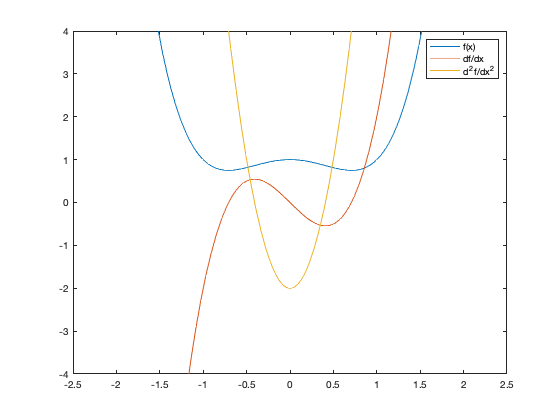


hold on; fplot(d2fdx2);  legend("f(x)", "df/dx", "d^2f/dx^2");

xlim([-2.5 2.5])
ylim([-4 4])

d2fdx2fn = matlabFunction(d2fdx2)

d2fdx2fn = function_handle with value:
    @(x)x.^2.*1.2e+1-2.0


d2fdx2fn(critical_pt_x) 

ans = -2

if d2fdx2fn(critical_pt_x) < 0
    disp("Critical Point is a Relative Maximum!")
else
    disp("Critical Point is a Relative Minimum!")
end

Critical Point is a Relative Maximum!


## Exercise 24.4.1

syms x y f(x,y)
f(x, y) = 4 + x^3 + y^3 - (3 * x * y);
ffn = matlabFunction(f)

ffn = function_handle with value:
    @(x,y)x.*y.*-3.0+x.^3+y.^3+4.0


pdfdx = diff(f, x)

$$pdfdx(x, y) = 3\,x^{2}-3\,y$$

pdfdy = diff(f, y)

$$pdfdy(x, y) = 3\,y^{2}-3\,x$$

gradient = [pdfdx; pdfdx]

$$gradient(x, y) = \left(\begin{array}{c} 3\,x^{2}-3\,y\\ 3\,x^{2}-3\,y \end{array}\right)$$

pdfdxfn = matlabFunction(pdfdx)

pdfdxfn = function_handle with value:
    @(x,y)y.*-3.0+x.^2.*3.0


pdfdyfn = matlabFunction(pdfdy)

pdfdyfn = function_handle with value:
    @(x,y)x.*-3.0+y.^2.*3.0


gradientFn = matlabFunction(gradient)

gradientFn = function_handle with value:
    @(x,y)[y.*-3.0+x.^2.*3.0;y.*-3.0+x.^2.*3.0]


cp_x = fzero(@(x) pdfdx(x, 0), 0)

cp_x = 0

cp_y = fzero(@(y) pdfdx(cp_x, y), 0)

cp_y = 0

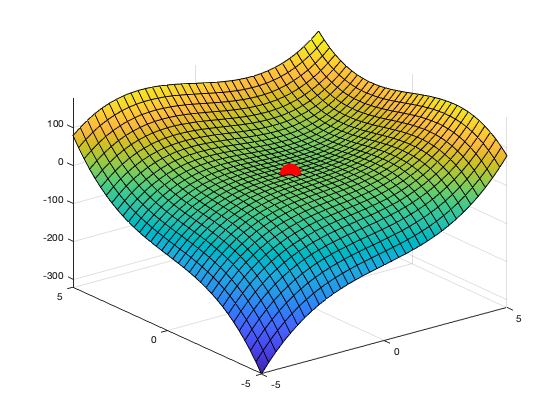

clf; fsurf(f); hold on; plot3(cp_x, cp_y, double(f(cp_x, cp_y)), 'r.', 'MarkerSize', 75)

## Exercise 24.4.2

syms x y f(x,y)
f(x, y) = (3 * x^2 * y) + y^3 - (3 * x^2) - (3 * y^2) + 2

$$f(x, y) = 3\,x^{2}\,y-3\,x^{2}+y^{3}-3\,y^{2}+2$$

ffn = matlabFunction(f)

ffn = function_handle with value:
    @(x,y)x.^2.*y.*3.0-x.^2.*3.0-y.^2.*3.0+y.^3+2.0


pdfdx = diff(f, x)

$$pdfdx(x, y) = 6\,x\,y-6\,x$$

pdfdy = diff(f, y)

$$pdfdy(x, y) = 3\,x^{2}+3\,y^{2}-6\,y$$

gradient = [pdfdx; pdfdx]

$$gradient(x, y) = \left(\begin{array}{c} 6\,x\,y-6\,x\\ 6\,x\,y-6\,x \end{array}\right)$$

pdfdxfn = matlabFunction(pdfdx)

pdfdxfn = function_handle with value:
    @(x,y)x.*-6.0+x.*y.*6.0


pdfdyfn = matlabFunction(pdfdy)

pdfdyfn = function_handle with value:
    @(x,y)y.*-6.0+x.^2.*3.0+y.^2.*3.0


gradientFn = matlabFunction(gradient)

gradientFn = function_handle with value:
    @(x,y)[x.*-6.0+x.*y.*6.0;x.*-6.0+x.*y.*6.0]


cp_x = fzero(@(x) pdfdx(x, 0), 0)

cp_x = 0

cp_y = fzero(@(y) pdfdx(cp_x, y), 0)

cp_y = 0

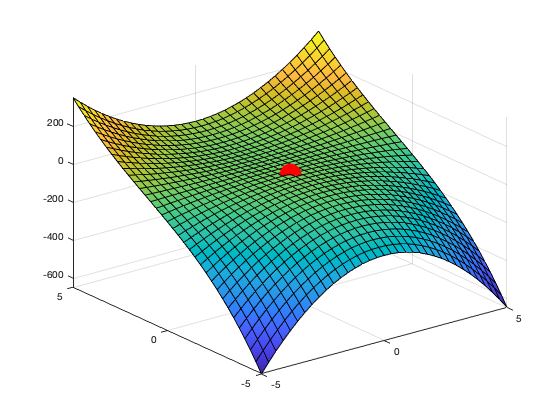

clf; fsurf(f); hold on; plot3(cp_x, cp_y, double(f(cp_x, cp_y)), 'r.', 'MarkerSize', 75)

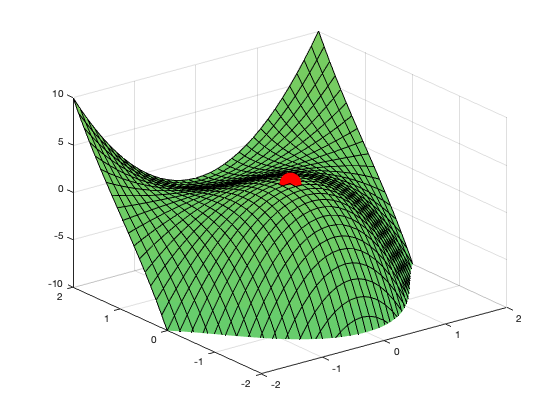

figure; clf; fsurf(f); hold on; plot3(cp_x, cp_y, double(f(cp_x, cp_y)), 'r.', 'MarkerSize', 75)
xlim([-2, 2])
ylim([-2, 2])
zlim([-10, 10])

pd2fdx2(x, y) = diff(pdfdx, x)

$$pd2fdx2(x, y) = 6\,y-6$$

pd2fdx2(cp_x, cp_y)

$$ans = -6$$

pd2fdy2(x, y) = diff(pdfdy, y)

$$pd2fdy2(x, y) = 6\,y-6$$

pd2fdy2(cp_x, cp_y)

$$ans = -6$$

Since the 2nd derivitives are negative in both directions, this is a local maximum

## Exercise 24.4.1

syms x y f(x,y)
f(x, y) = 4 + x^3 + y^3 - (3 * x * y);
ffn = matlabFunction(f)

ffn = function_handle with value:
    @(x,y)x.*y.*-3.0+x.^3+y.^3+4.0


pdfdx = diff(f, x)

$$pdfdx(x, y) = 3\,x^{2}-3\,y$$

pdfdy = diff(f, y)

$$pdfdy(x, y) = 3\,y^{2}-3\,x$$

gradient = [pdfdx; pdfdx]

$$gradient(x, y) = \left(\begin{array}{c} 3\,x^{2}-3\,y\\ 3\,x^{2}-3\,y \end{array}\right)$$

pdfdxfn = matlabFunction(pdfdx)

pdfdxfn = function_handle with value:
    @(x,y)y.*-3.0+x.^2.*3.0


pdfdyfn = matlabFunction(pdfdy)

pdfdyfn = function_handle with value:
    @(x,y)x.*-3.0+y.^2.*3.0


gradientFn = matlabFunction(gradient)

gradientFn = function_handle with value:
    @(x,y)[y.*-3.0+x.^2.*3.0;y.*-3.0+x.^2.*3.0]


cp_x = fzero(@(x) pdfdx(x, 0), 0)

cp_x = 0

cp_y = fzero(@(y) pdfdx(cp_x, y), 0)

cp_y = 0

clf; fsurf(f); hold on; plot3(cp_x, cp_y, double(f(cp_x, cp_y)), 'r.', 'MarkerSize', 75)

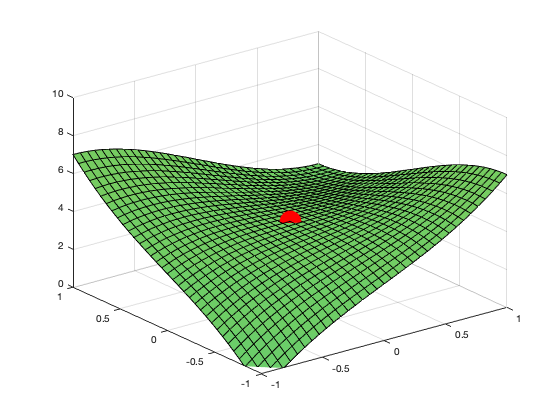

figure; clf; fsurf(f); hold on; plot3(cp_x, cp_y, double(f(cp_x, cp_y)), 'r.', 'MarkerSize', 75)
xlim([-1, 1])
ylim([-1, 1])
zlim([0, 10])

pd2fdx2(x, y) = diff(pdfdx, x)

$$pd2fdx2(x, y) = 6\,x$$

pd2fdx2(cp_x, cp_y)

$$ans = 0$$

pd2fdy2(x, y) = diff(pdfdy, y)

$$pd2fdy2(x, y) = 6\,y$$

pd2fdy2(cp_x, cp_y)

$$ans = 0$$

Since the 2nd derivitives are zero in both directions, this critical point can't be classified.